# Optimisation and Statistical Data Analysis

# Exercise Set 9 Solutions

## Problem 1

### Part a

A 95% confidence interval for $\theta\mid \text{ stats}_{2011}$ is 

a=1; b=1;         % uniform prior
s=30546;          % boys
n=s+29415;        % girls
a=s+a; b=n-s+b;   % update 
CI95=betainv([0.025,0.975],a,b)  % 95 percent confidence interval

CI95 =     0.5054    0.5134


### Part b

The posterior probability that $\theta\leq 0.5$ is

betacdf(0.5,a,b)

ans = 1.9291e-06

and so the posterior probability that $\theta> 0.5$ is 

format long; 1-ans

ans =    0.999998070929810


Revert to default display format. 

format

### Part c

Modify the code from slide 13. Notice the "off-by-1" indexing of `p_pred` in the last line.

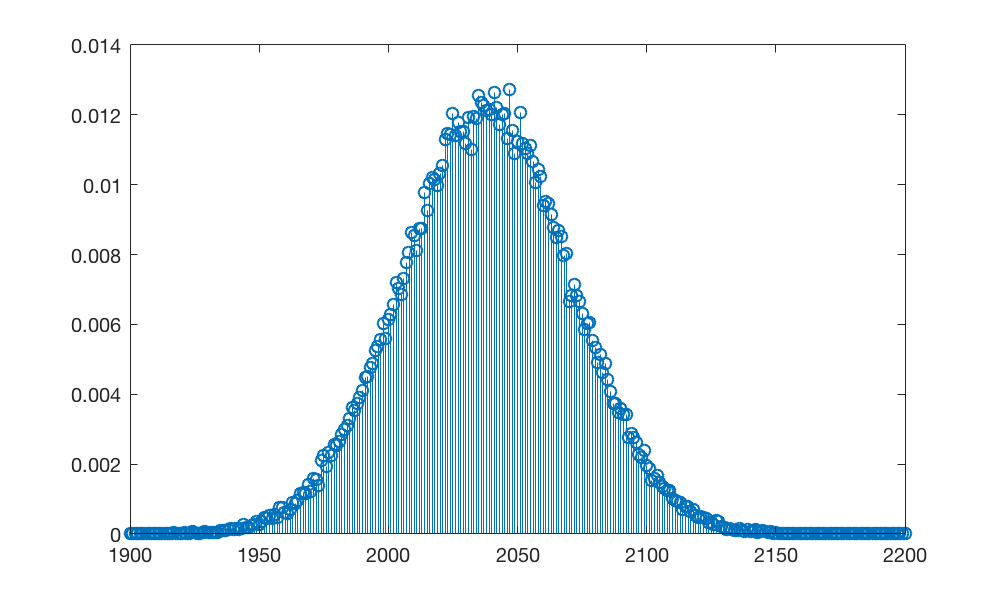

rng default; % for replicability
Nsamp=100000;
theta=betarnd(a,b,Nsamp,1); % samples of theta
n_pred=4000;
s_pred=binornd(n_pred,theta);     % samples of s
p_pred=histcounts(s_pred,-0.5:n_pred+0.5)/Nsamp;
figure; set(gcf,'position',[0 0 500 300])
stem(1900:2200,p_pred(1901:2201)) 

The "noise" is due to the approximation and could be reduced by increasing `Nsamp`, the number of Monte Carlo samples. 

 To obtain a smooth (but still approximate) plot use

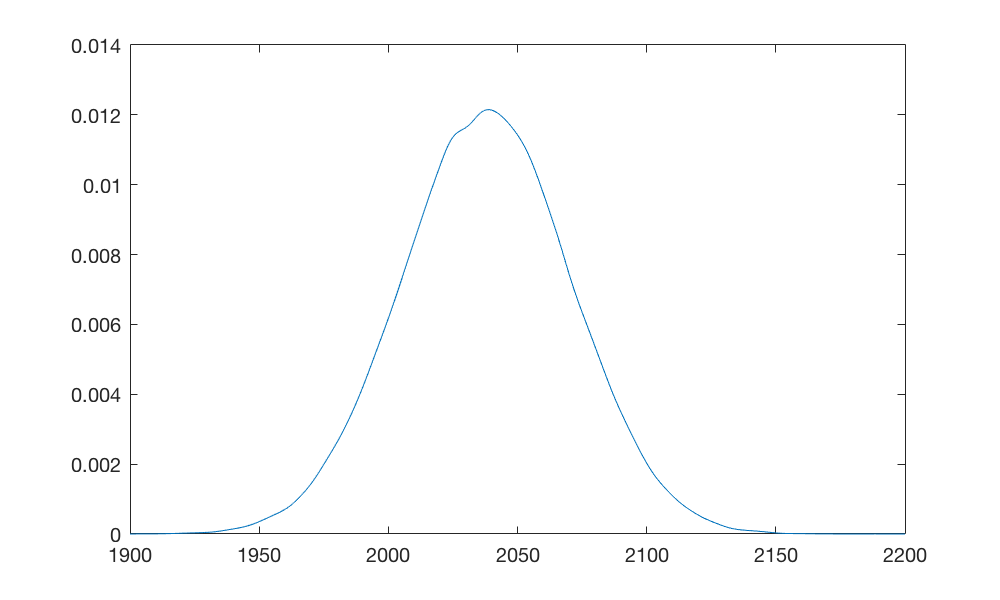

ksdensity(s_pred,1900:2200)

The posterior predictive probability that the number of male births is > 2000 is approximately

sum(s_pred>2000)/Nsamp

ans = 0.8738

which is high, but much smaller than the answer in Part b. Here there is uncertainty (randomness) in observations **and** uncertainly about $\theta$, so the distribution has more spread than in Part b, where there is only the uncertainty about $\theta$. 

### Part d

According to 

[http://pxnet2.stat.fi/PXWeb/pxweb/fi/StatFin/StatFin__vrm__synt/statfin_synt_pxt_001.px/?rxid=4de473ce-429f-46f6-924a-4d464318b342](http://pxnet2.stat.fi/PXWeb/pxweb/fi/StatFin/StatFin__vrm__synt/statfin_synt_pxt_001.px/?rxid=4de473ce-429f-46f6-924a-4d464318b342)

the number of boys born in Finland in 2012 was 30308 and the number of girls was 29185. 

Update the parameters of the updated posterior distribution and compute its 95% confidence interval.

s=30308;          % boys
n=s+29185;        % girls
a=s+a; b=n-s+b;   % update 
CI95=betainv([0.025,0.975],a,b)

CI95 =     0.5066    0.5123


The interval is a bit narrower than in part (a) because there is more data.

## Problem 2

### Part a

Plot the density function of the prior for CTR. 

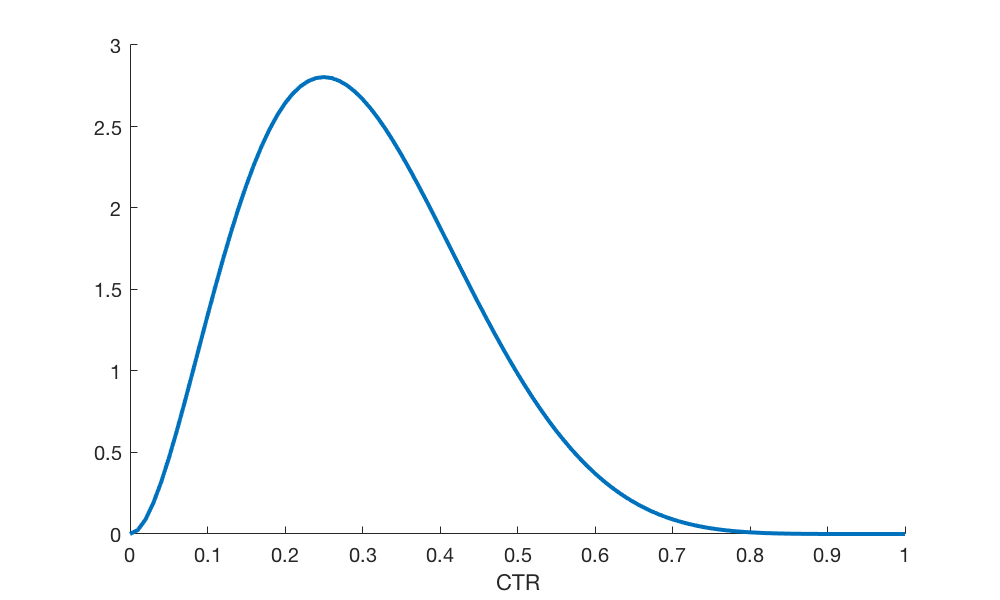

a=3; b=7;                   % parameters of beta prior
CTR=0:.01:1;                % CTR values for plot
plot(CTR,betapdf(CTR,a,b),'linewidth',2)
box off, xlabel('CTR')

Plot the prior predictive density using Monte Carlo approximation as in slide 13. 

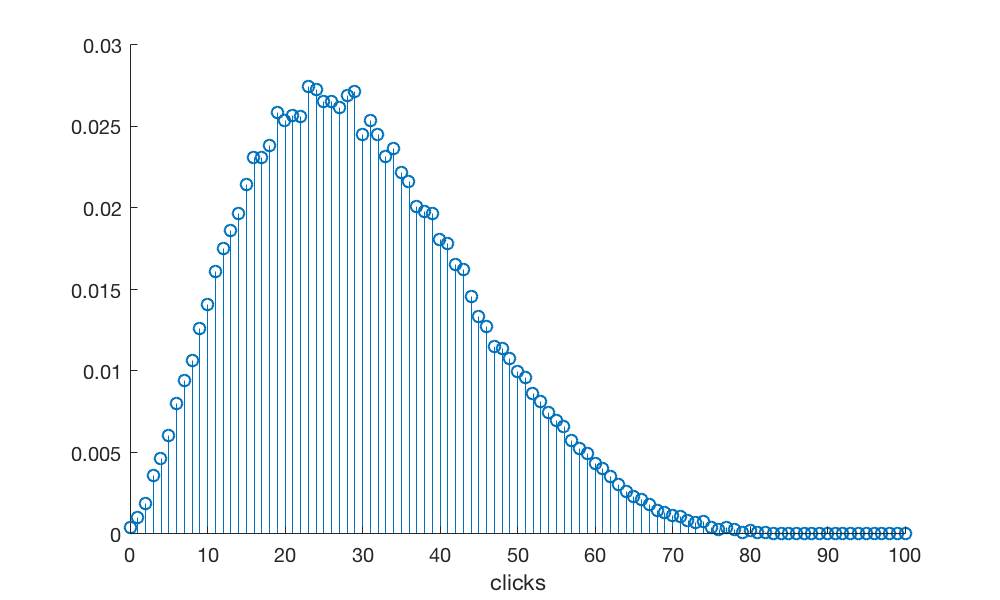

rng default, Nsamp=100000;
CTR_samp=betarnd(a,b,Nsamp,1);
n_pred=100;     % number of visits
s_pred=binornd(n_pred,CTR_samp);
p_pred=histcounts(s_pred,-0.5:n_pred+0.5)/Nsamp;
stem(0:n_pred,p_pred);
box off, xlabel('clicks') 

### Part b

Generate Monte Carlo samples from the posterior distribution of the CTR difference (as in slide 23) and plot the density.

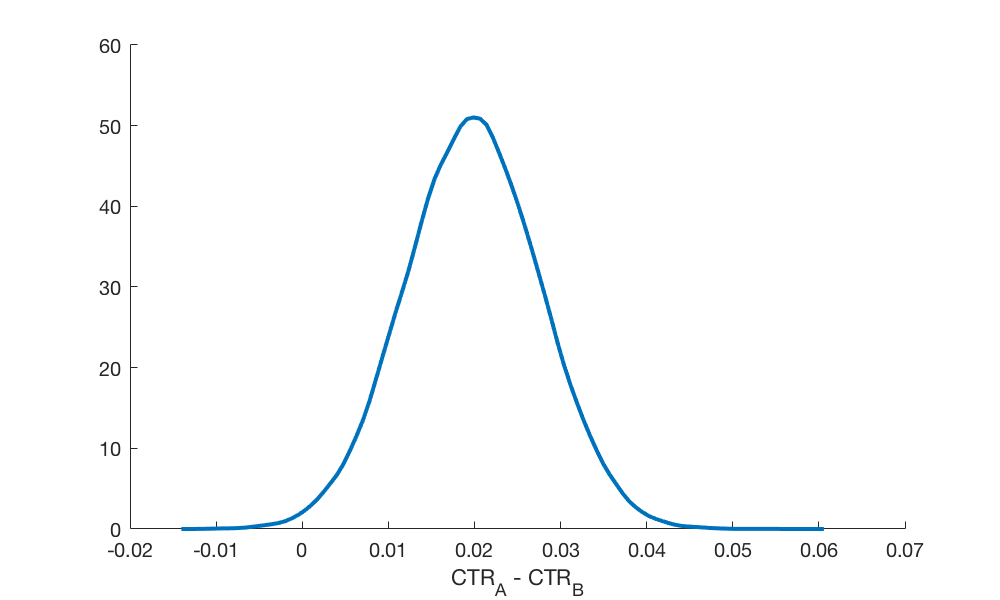

s=[2654 2214]; n=[7706 6821];  % observations
rng default 
Nsamp=100000;
a=s+a; b=n-s+b;
CTR_A=betarnd(a(1),b(1),Nsamp,1);
CTR_B=betarnd(a(2),b(2),Nsamp,1);
[p_diff,ctr]=ksdensity(CTR_A-CTR_B);
plot(ctr,p_diff,'linewidth',2)
box off, xlabel('CTR_{A} - CTR_{B}')

The probability that the difference is positive is 

Prob=sum(CTR_A>CTR_B)/Nsamp

Prob = 0.9947

It is almost certain that the ad with image A has a higher click-through rate than the ad with image B. 